Импортирование данных

spectra      = importdata('spectra.csv');
star_names   = importdata('star_names.csv');
lambda_start = importdata('lambda_start.csv');
lambda_delta = importdata('lambda_delta.csv');

n_stars      = size(star_names,1); % количество звезд

Определение используемых физических констант

light_speed= 299792.458;
lambdaPr    = 656.28;

Задание диапазона длин волн

nObs       = size(spectra, 1);
lambda_end = lambda_start + (nObs - 1) * lambda_delta;
lambda     = (lambda_start : lambda_delta : lambda_end)';

Рассчет доплеровского смещения и скоростей звезд относительно земли


speed = zeros(n_stars,1);

for i = 1 : n_stars

    cur_spectra = spectra(:, i);    % Для конкретной звезды:
    [Ha, idx]   = min(cur_spectra); % определение длины волны
    lambda_Ha   = lambda(idx);      % при На

    z           = (lambda_Ha / lambdaPr) - 1;
    speed(i)    = z * light_speed;
end

Построение графика

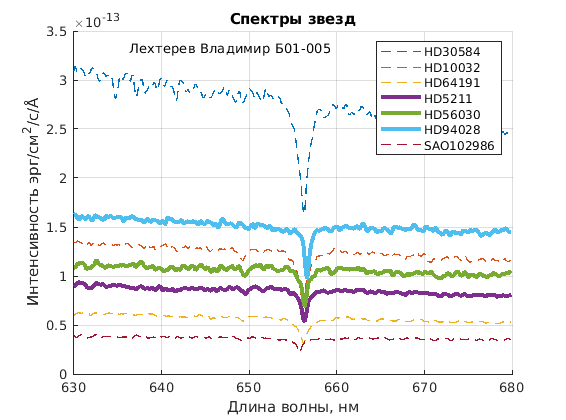

fg1 = figure;
hold on;
grid on;

for i = 1:n_stars

    cur_spectra = spectra(:, i);

    if speed(i) > 0
        plot(lambda, cur_spectra, "LineStyle","-", "LineWidth", 3);
    else
        plot(lambda, cur_spectra, "LineStyle","- -","LineWidth", 1);
    end
end

% Автоматическое позиционирование текста
ref_offset_x = 0.01;
text_x       = xlim;
text_x       = text_x(1)*(1 + ref_offset_x);

ref_offset_y = -0.05;
text_y       = ylim;
text_y       = text_y(2)*(1 + ref_offset_y);

text(text_x, text_y, 'Лехтерев Владимир Б01-005');
title({'Спектры звезд'});
xlabel('Длина волны, нм');
ylabel(['Интенсивность эрг/см^2/с/' char(197)]);
legend(star_names);

set(fg1, 'Visible', 'on');
hold off

Сохранение графика

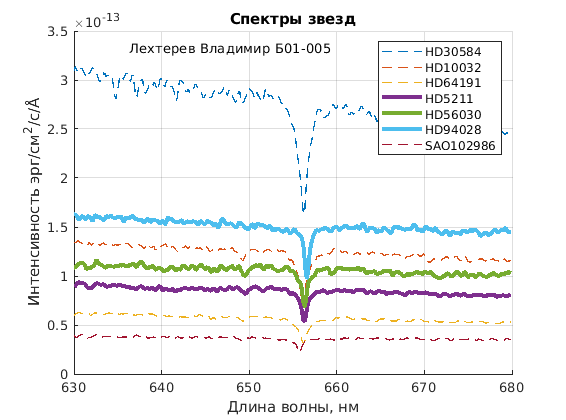

saveas(fg1, 'spectra.png');

Отдаляющиеся звезды

movaway = star_names(speed > 0);